## Non linear model of the system

s=tf('s');

#### Linearized model of the system

A = {}; B = {}; C = [0 1 0]; D = 0; sys={};

for k = 1:length(x_eq)
    A_test = [                    0                                                         dfx_function(x_eq(k),I_eq(k))/m     dfy_function(x_eq(k),I_eq(k))/m;
                                  1                                                                              0                           0;
             -dLx_function(x_eq(k),I_eq(k))*I_eq(k)/(R1*(tau_function(x_eq(k),I_eq(k))))                         0              -1/tau_function(x_eq(k),I_eq(k))];
    
    B_test = [0; 0; 1/(R1*tau_function(x_eq(k),I_eq(k)))];
    
   
    A{k} = A_test;
    B{k} = B_test;
    sys{k}=ss(A{k},B{k},C,D);

end

*Disturbances transfer functions in the equilibrum positions*

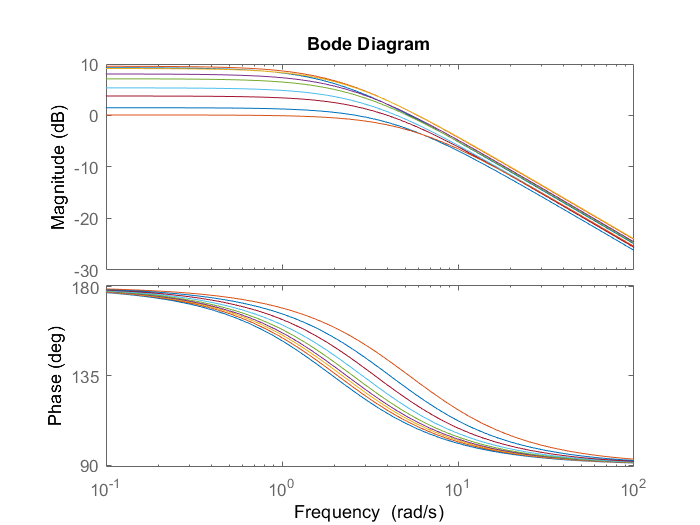

figure("Name","Bode disturbances tf | eq")

for i = 1:length(x_eq)
    H{i}= (-dLx_function(x_eq(i),I_eq(i))*I_eq(i)/(R1*(tau_function(x_eq(i),I_eq(i)))))/(s+1/(tau_function(x_eq(i),I_eq(i))));
    
    hold on
    bode(H{i});
    [numH{i}, denH{i}]=tfdata(H{i}, 'v');
end

*Electrical model transfer function*

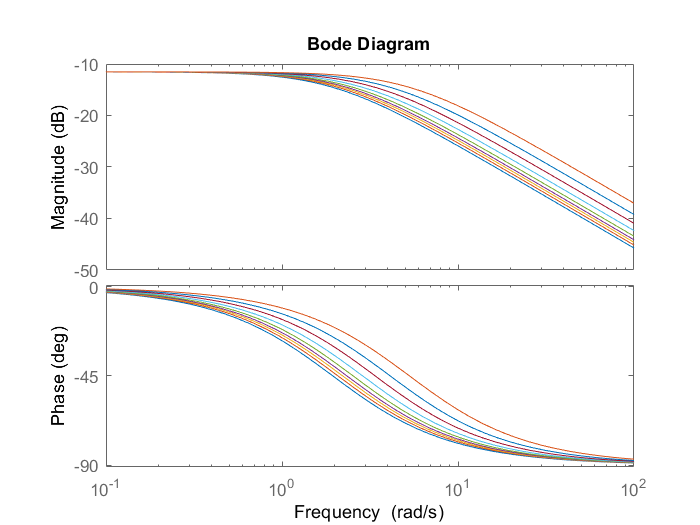

figure("Name","Bode electrical model tf")

for i = 1:length(x_eq)
    Gi{i}=(1/(R1*(tau_function(x_eq(i),I_eq(i)))))/(s+1/(tau_function(x_eq(i),I_eq(i))));

    hold on
    bode(Gi{i});
    [numi{i}, deni{i}]=tfdata(Gi{i}, 'v');
end

*Mechanical model linearize around the equilibrum position*

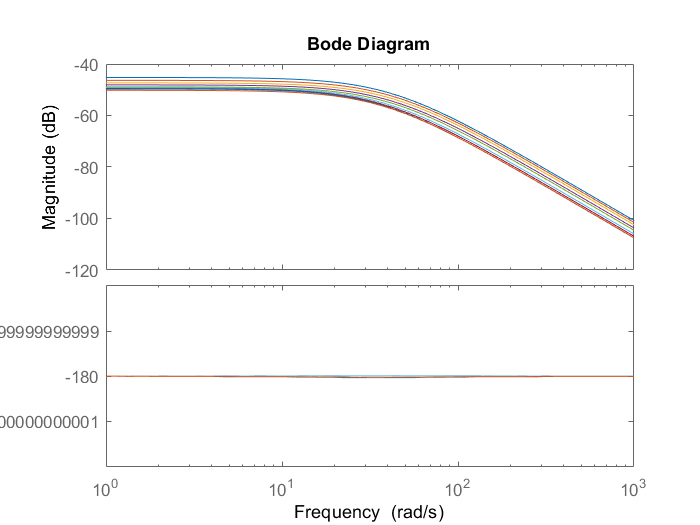

Cm=[1 0];
figure("Name","Bode linearized mehcanical model tf | eq")

for i = 1:length(x_eq)
    Am{i} = [0 1; dfx_function(x_eq(i),I_eq(i))/m  0];
    Bm{i}=[0; dfy_function(x_eq(i),I_eq(i))/m];
    Gm{i}=Cm*((s*eye(2)-Am{i})^(-1))*Bm{i};
    
    hold on;
    bode(Gm{i});
    [numGm{i}, denGm{i}]=tfdata(Gm{i}, 'v');
end

#### Control strategies - Cascade loops with PI controlles

*Parameters*

wc_i=150;
phim_i=90;
wc_m=15;
phim_m=60;

*Tuning of the regulator of position*

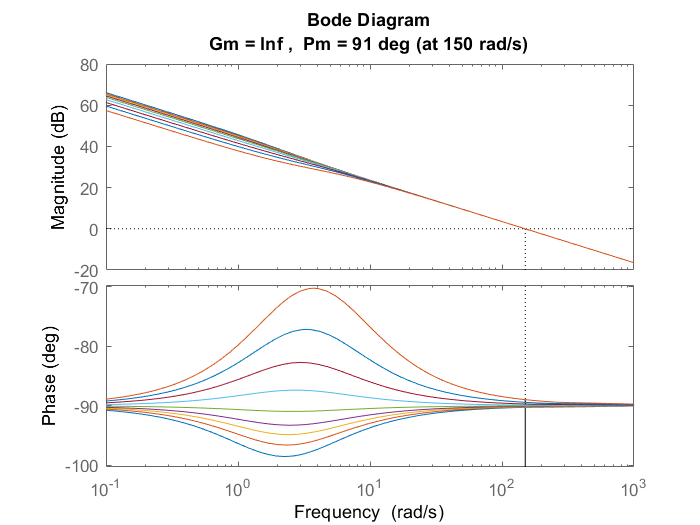

opt = pidtuneOptions('PhaseMargin',phim_i); 

figure("Name","Margin Li")

for j = 1:length(x_eq)
    REG_i{j} = pidtune(Gi{j},'PI',wc_i,opt);
    REGi{j} = REG_i{j}.Kp + REG_i{j}.Ki/s;
    Li{j} = Gi{j}*REGi{j};
    
    hold on;
    margin(Li{j});
end

*Tuning of the disturnace compansator*

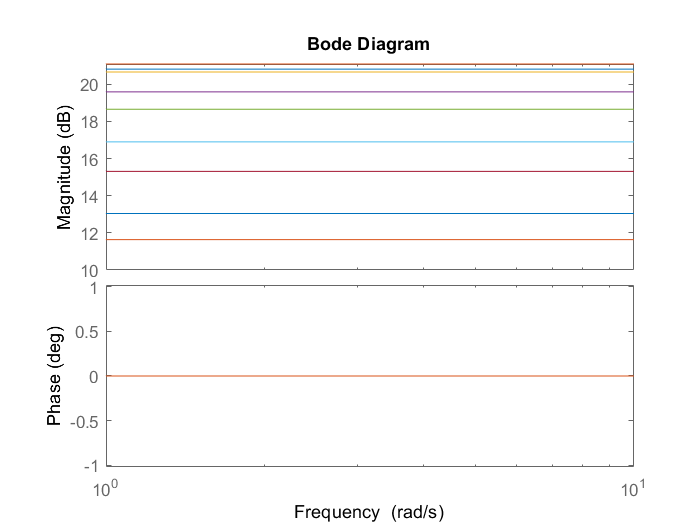

figure("Name","Bode disturbance compensators")
for i = 1:length(x_eq)
    Cd{i}=-H{i}/Gi{i}; 
    hold on;
    bode(Cd{i});

    [numCd{i}, denCd{i}]=tfdata(Cd{i}, 'v');

end

gains = [dcgain(Cd{1}) dcgain(Cd{2}) dcgain(Cd{3}) dcgain(Cd{4}) dcgain(Cd{5}) dcgain(Cd{6}) dcgain(Cd{7}) dcgain(Cd{8}) dcgain(Cd{9})];

*Tuning of the regulator of position*

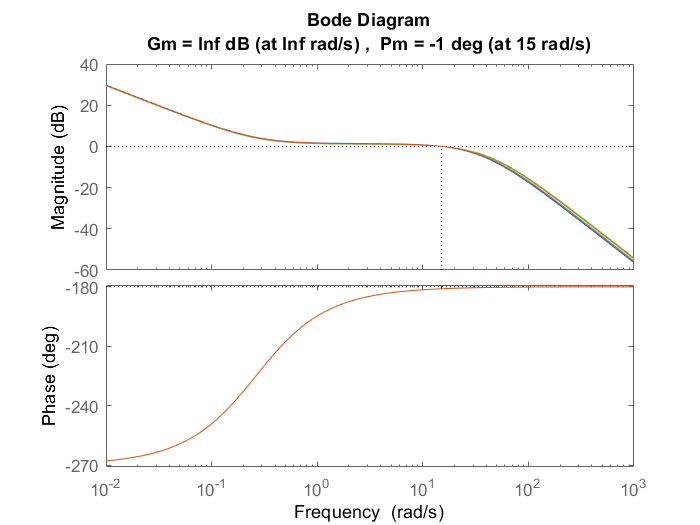

opt = pidtuneOptions('PhaseMargin',phim_m); 

figure("Name","Margin Lm")
for j = 1:length(x_eq)
    REG_m{j} = pidtune(Gm{j},'PI',wc_m,opt);
    REGm{j} = REG_m{j}.Kp + REG_m{j}.Ki/s;
    Lm{j} = Gm{j}*REGm{j};
    
    hold on
    margin(Lm{j});
end

*Values for the look-up tables*

Kp_i = [REG_i{1}.Kp REG_i{2}.Kp REG_i{3}.Kp REG_i{4}.Kp REG_i{5}.Kp REG_i{6}.Kp REG_i{7}.Kp REG_i{8}.Kp REG_i{9}.Kp];
Ki_i = [REG_i{1}.Ki REG_i{2}.Ki REG_i{3}.Ki REG_i{4}.Ki REG_i{5}.Ki REG_i{6}.Ki REG_i{7}.Ki REG_i{8}.Ki REG_i{9}.Ki];
for i = 1:length(x_eq)
    Ti_i(i) = Kp_i(i)/Ki_i(i);
end

Kp_m = [REG_m{1}.Kp REG_m{2}.Kp REG_m{3}.Kp REG_m{4}.Kp REG_m{5}.Kp REG_m{6}.Kp REG_m{7}.Kp REG_m{8}.Kp REG_m{9}.Kp];
Ki_m = [REG_m{1}.Ki REG_m{2}.Ki REG_m{3}.Ki REG_m{4}.Ki REG_m{5}.Ki REG_m{6}.Ki REG_m{7}.Ki REG_m{8}.Ki REG_m{9}.Ki];

 for i=1:length(x_eq)
     Ti_m(i)=Kp_m(i)/Ki_m(i);
 end

x_eq_increasing = fliplr(x_eq);
Kp_i_increasing = fliplr(Kp_i);
Ti_i_increasing = fliplr(Ti_i);
Kp_m_increasing = fliplr(Kp_m);
Ti_m_increasing = fliplr(Ti_m);
gains_increasing = fliplr(gains);


## Control Code - old

%% cascade loops with PI controller for the position and current control
wc_i=150;
phim_i=80;

opt = pidtuneOptions('PhaseMargin',phim_i);

%tuning of the disturnace compansator
figure("Name","Bode disturbance compensators")
for i = 1:length(x_eq)
    Cd{i} = -H{i}/Gi{i}; 
    hold on;
    bode(Cd{i});

    [numCd{i}, denCd{i}]=tfdata(Cd{i}, 'v');
end

% guadagni di tutti i compensatori
gains = [dcgain(Cd{1}) dcgain(Cd{2}) dcgain(Cd{3}) dcgain(Cd{4}) dcgain(Cd{5}) dcgain(Cd{6}) dcgain(Cd{7}) dcgain(Cd{8}) dcgain(Cd{9})];

First we stabilize the system using an internal loop that is robust and stabilize the system in all equilibum points

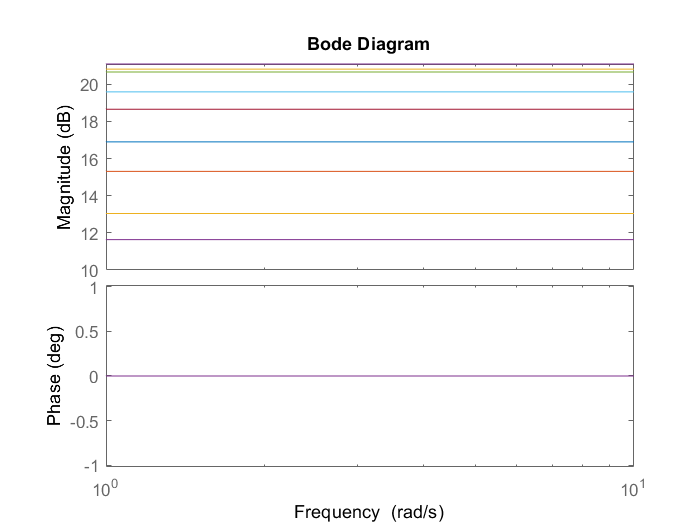

R_stabilizer = (s+25)/(s+400);

for i = 1:length(x_eq)
    L_stabilizer{i} = R_stabilizer*Gm{i};
    [~, feedback_gains{i}] = rlocus(L_stabilizer{i});
end


gain_stab{1} = feedback_gains{1}(22);
gain_stab{2} = feedback_gains{2}(22);
gain_stab{3} = feedback_gains{3}(22);
gain_stab{4} = feedback_gains{4}(23);
gain_stab{5} = feedback_gains{5}(24);
gain_stab{6} = feedback_gains{6}(24);
gain_stab{7} = feedback_gains{7}(25);
gain_stab{8} = feedback_gains{8}(28);
gain_stab{9} = feedback_gains{9}(28);

F_stable_f{1} = feedback(L_stabilizer{1}, gain_stab{1});
F_stable_f{2} = feedback(L_stabilizer{2}, gain_stab{2});
F_stable_f{3} = feedback(L_stabilizer{3}, gain_stab{3});
F_stable_f{4} = feedback(L_stabilizer{4}, gain_stab{4});
F_stable_f{5} = feedback(L_stabilizer{5}, gain_stab{5});
F_stable_f{6} = feedback(L_stabilizer{6}, gain_stab{6});
F_stable_f{7} = feedback(L_stabilizer{7}, gain_stab{7});
F_stable_f{8} = feedback(L_stabilizer{8}, gain_stab{8});
F_stable_f{9} = feedback(L_stabilizer{9}, gain_stab{9});

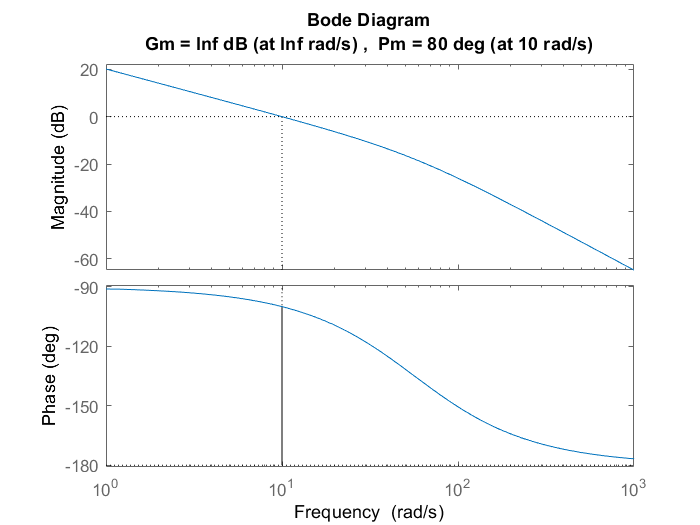

wc_m=10;
phim_m=80;

opt = pidtuneOptions('PhaseMargin',phim_m); 
REG_m1_f = pidtune(F_stable_f{1},'PI',wc_m,opt);
REG_m2_f = pidtune(F_stable_f{2},'PI',wc_m,opt);
REG_m3_f = pidtune(F_stable_f{3},'PI',wc_m,opt);
REG_m4_f = pidtune(F_stable_f{4},'PI',wc_m,opt);
REG_m5_f = pidtune(F_stable_f{5},'PI',wc_m,opt);
REG_m6_f = pidtune(F_stable_f{6},'PI',wc_m,opt);
REG_m7_f = pidtune(F_stable_f{7},'PI',wc_m,opt);
REG_m8_f = pidtune(F_stable_f{8},'PI',wc_m,opt);
REG_m9_f = pidtune(F_stable_f{9},'PI',wc_m,opt);


Kp_mf=[REG_m1_f.Kp REG_m2_f.Kp REG_m3_f.Kp REG_m4_f.Kp REG_m5_f.Kp REG_m6_f.Kp REG_m7_f.Kp REG_m8_f.Kp REG_m9_f.Kp];
Ki_mf=[REG_m1_f.Ki REG_m2_f.Ki REG_m3_f.Ki REG_m4_f.Ki REG_m5_f.Ki REG_m6_f.Ki REG_m7_f.Ki REG_m8_f.Ki REG_m9_f.Ki];

 for i=1:length(x_eq)
     Ti_mf(i)=Kp_mf(i)/Ki_mf(i);
 end

Kp_mf_increasing=fliplr(Kp_mf);
Ti_mf_increasing=fliplr(Ti_mf);

%%third strategy feedback linearization control + PI external

G_linearization=1/(s^2+120*s+3600);
REG_linearization= pidtune(G_linearization ,'PI',wc_m,opt);

L_linearization=REG_linearization*G_linearization;
  
figure
margin(L_linearization);

## Control Code - new

*First strategy: cascade loops with PI controller for the position and current control*

wc_i=150;
phim_i=80;
opt = pidtuneOptions('PhaseMargin',phim_i); 
wc_m=10;
phim_m=80;
opt = pidtuneOptions('PhaseMargin',phim_m);

R_stabilizer=(s+25)/(s+400);

Kp_i = []; Ki_i = []; Ti_i = [];

for j = 1:length(x_eq)
    REG_i{j} = pidtune(Gi{j},'PI',wc_i,opt);
    REGi{j}=REG_i{j}.Kp+REG_i{j}.Ki/s;
    Li_{j}=Gi{j}*REGi{j};

    Kp_i = [REG_i{j}.Kp Kp_i]
    Ki_i = [Kp_i REG_i{j}.Ki]
    Ti_i = [REG_i{j}.Kp/REG_i{j}.Ki Ti_i];
    
    Cd{j} = -H{j}/Gi{j};
    [numCd{j}, denCd{j}]=tfdata(Cd{j}, 'v');
    
    
    % first we stabilize the system using an internal loop that is robust and
    % stabilize the system in all equilibum points
    L_stabilizer{i} = R_stabilizer*Gm{i};
    [~, feedback_gains{i}] = rlocus(L_stabilizer{i});


end
 

x_eq_increasing = fliplr(x_eq);
gains = [dcgain(Cd{1}) dcgain(Cd{2}) dcgain(Cd{3}) dcgain(Cd{4}) dcgain(Cd{5}) dcgain(Cd{6}) dcgain(Cd{7}) dcgain(Cd{8}) dcgain(Cd{9})];
%gains_increasing=fliplr(gains);




% gain_stab1=k1(24);
% gain_stab2=k2(22);
% gain_stab3=k3(22);
% gain_stab4=k4(23);
% gain_stab5=k5(24);
% gain_stab6=k6(24);
% gain_stab7=k7(25);
% gain_stab8=k8(28);
gain_stab9 = feedback_gains{9}(23);


Kp_mf = []; Ki_mf = []; Ti_mf = [];

for j = 1:length(x_eq)
    F_stable_f{j}=feedback(L_stabilizer{j}, gain_stab9);
    REG_m_f{j} = pidtune(F_stable_f{j},'PI',wc_m,opt);
    
    Kp_mf = [REG_m_f{j}.Kp Kp_mf]
    Ki_mf = [Kp_mf REG_m_f{j}.Ki]
    Ti_mf = [REG_m_f{j}.Kp/REG_m_f{j}.Ki Ti_mf];
   
end


*Third strategy feedback linearization control + PI external*


G_linearization=1/(s^2+120*s+3600);
REG_linearization= pidtune(G_linearization ,'PI',wc_m,opt);

 L_linearization=REG_linearization*G_linearization;
  
 figure
 margin(L_linearization);
%LQR strategy, in order to find an LQ controller that is able to stabilize
%the system and have a good reference following
%definition of the parameter

%without integral action

K_pos_increasing_lq = []; K_vel_increasing_lq = [];

for j = 1: length(x_eq)
    R_lq{j} = abs(round(89.5-10*j));
    Q_lq{j} = [j+1 0; 0 0.5];
    
    [K_lq{j},S_lq{j},P_lq{j}] = lqr(Am{j},Bm{j},Q_lq{j},R_lq{j});
    K_pos_increasing_lq = [K_lq{j}(1) K_pos_increasing_lq];
    K_vel_increasing_lq = [K_lq{j}(2) K_vel_increasing_lq];

end


%with integral action around an equilibrum point

K_pos_increasing_lqi = []; K_vel_increasing_lqi = []; K_int_increasing_lqi = [];


for j = 1:length(x_eq)
    
    Aext_{j} = [0 1 0; dfx_function(x_eq(j),I_eq(j))/m  0 0; -1 0 0];
    Bext_{j} = [0; dfy_function(x_eq(j),I_eq(j))/m; 0];
    
    R_lqi{j} = = abs(round(8.5-j));
    Q_lqi{j} = [0.1*(j+1) 0 0; 0 0.5 0; 0 0 1];
    
    [K_lqi{j},S_lqi{j},P_lqi{j}] = lqr(Aext_{j},Bext_{j},Q_lqi{j},R_lqi{j});
    K_pos_increasing_lqi = [K_lqi{j}(1) K_pos_increasing_lqi];
    K_vel_increasing_lqi = [K_lqi{j}(2) K_vel_increasing_lqi];
    K_int_increasing_lqi = [K_lqi{j}(3) K_int_increasing_lqi];

end

I_eq_increasing=fliplr(I_eq);

Other possible LQI

A_int=[0 1 0; 0 0 0; -1 0 0];


K_pos_increasing_int = []; K_vel_increasing_int = []; K_int_increasing_int = [];

for j = 1:lenth(x_eq)
    B_int{j}=[0; (K_function(x_eq(j))*(L_function(x_eq(j),I_eq(j))^2))/((Afe^2)*m0) ;0];
    
    R_int{j} = abs(round(89.5-10*j))
    Q_int{j} = [0.1*(j+1) 0 0; 0 0.5 0; 0 0 100];
    
    [K_int{j},S_int{j},P_int{j}] = lqr(A_int,B_int{j},Q_int{j},R_int{j});
    K_pos_increasing_int = [K_int{j}(1) K_pos_increasing_int]
    K_vel_increasing_int = [K_int{j}(2) K_vel_increasing_int]
    K_int_increasing_int = [K_int{j}(3) K_int_increasing_int]

end
